# **Scripting Habits, Readability, and Reproducibility**

### *Or, how I learned to stop worry and love the machine.*

## Why we want 'Clean Code'?

- Coding is our tool to process **research-vital **information.

- We're taking information through a processing pipeline. 

- We will inevitably have to share or review old code. 

#### Do we want this?

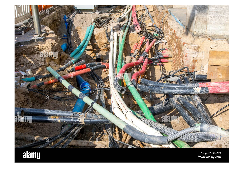

mess = imread('messy_pipes.jpg'); %loads image
imshow(mess); %displays image

#### Or this?

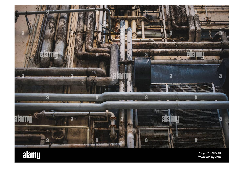

neat = imread('neat_pipes.jpg'); %loads image
imshow(neat); %displays image

- It might seem to be a silly analogy, ***but you will run across either your own or other's scripts like this!!!***

- The temptation is always to say "Well, I know how my own code works, and I work alone" 

**This is changing in science, and you will also forget how it worked!**

### *The takeaway from this whole thing is that we want to keep human intervention to an absolute minimum.*

#### **Clean Code Benefits**

- Flexibility - Easier to iterate and adapt.

- Repairability - Easier to fix mistakes.

- Communication - Easier to show someone what you're doing.

- Efficiency - You will be less likely to include redundant operations.

- Parrallelisation - You need very specific, controlled data structures to do parallel processing.

- Sanity - Your mental state will deteriorate when you are searching 500 instances of `xX.`

- **Reproducibility - **If we want to make Gorka happy, we should be sharing code that will instantly run on any computer without adaptation!

## **Code Design**

#### *Design your code before you write your code!*

- This is the norm in industry for a reason - It's easier to go somewhere if you have a map.

- In all our work we know, 1) Where we are now and 2) Where we're going.

- Design and then build code from here inwards.

- This can be relatively simple, but make a plan first!

%% Amplitude modulation for Inf_Cry Stimuli
% Aim - Use optimisation process to manipulate AM with the MPS analysis

% Parameters
% Load Stimuli
% Normalise stimuli
% Set MPS targets
% Use fMinsearch to iterate through MPS manipulation
% Normalise manipulated stimuli.
% Write wav files.

%% Functions (internal)
% Optimisation function (called for fmin)
% MPS function - called inside optimisation function.

#### *Keep the goal of your coding in mind!*

#### *Don't solve local problems at the expense of global ones!*

- This is pivotal for analyses and data manipulations.

- Every manipulation we do on data **removes some information which can never be reclaimed!**

- You will be really upset if you realise this at the very end.

#### Functional separation, master documents, code modularity.

- Some analysis pipelines can be thousands of lines long. Having everything in one place is not always sensible.

- fMRI analysis for example has pre-processing, first-level, and second level analyses within a single model.

- Break process pipelines up at logical 'joints' and keep a master document to run these from.

- In industry this is "code modularity"

%% FMRI - Canonical Contrast Pipeline

% Subject master - Contains the information for participants in analysis.
subjMat = 'study_subjects.mat';
% Pre processing 
[preOut] = pre_processing(subjMat);

pre-processedic_01
pre-processedic_02
pre-processedic_03


% First level
[firstOut] = first_level(preOut);

first_level_and_pre-processed_ic_01
first_level_and_pre-processed_ic_02
first_level_and_pre-processed_ic_03



% It's advisable to save outputs from each 'joint' of a script so that
% levels can be skipped if you make changes at only one area.

% etc etc etc

#### Keep scale manageable

- It's important to keep code together based on it's function, but also to not end up with such huge scripts that revisiting them is difficult. Modularise code where possible.

- It is also worthwhile separating scripts (and saving output) after **major processing times.** Running your pre-processing everytime is highly inefficient.

## **Script/Function Structure**

#### ***Put things in the same place every time.***

- We don't want to waste effort relocating parts of a script.

- We can abstract that different variables and processes have different categories of purpose.

- Accounting for Matlab being interprative* , keep these in the same relative locations.

- We want to avoid changing our working directory.

%% Script Title - Example First level.

% to avoid reduplications.
% clear all; close all; clc; 

%% Setting Pathing Structure!!


% Contains the following - but it only works when running a script or
% function as awhole, not line by line.
% 
% filePath = mfilename('fullpath');
% pTop = filePath(1:strfind(filePath,'01_scripts')-1);

[pTop] = ex_mfilepath
pDat = fullfile(pTop,'02_data')
pAna = fullfile(pTop,'03_analysis')
%Out paths
pOutBeh = fullfile(pAna,'behavioural','first_level') %behavrioual output
mkdir(pOutBeh);
pOutFmri = fullfile(pAna,'fmri','first_level');
mkdir(pOutFmri);

%Add paths to any required toolboxes etc.
addpath(fullfile(pTop,'04_toolboxes'))

% Parameters
smoothingKernal = 3;
fs = 48000;
nBlocks = 3;
rtThresh = 500;

% Setting the data to work on programmatically. 
subjs = dir(fullfile(pDat,'ic*')); subjs = {subjs.name}

%% From here on out, aim to be 100% programmatic.

for iS = 1:length(subjs)

    % Setting paths fully programmatically now
    pSubj = fullfile(pDat,subjs{iS})
    %Perform whatever operations on subject level etc.
end

** MATLAB is an interprative language, which means it interprets each individual line of code in order and thus you cannot call data that appears on subsequent lines of code in normal operation. The contrast to this would be Object Oriented Programming, or compiled languages.*

%% dir(fullfile()) is extremely useful with wildcards. Note what returns otherwise

dir(pDat)'

% General tip for creating path-related strings, fullfile() is much better
% as it will automatically generate correct path seperators for any
% operating system. Otherwise you will have to swap all your / and \ if you
% use linux/apple after PC.

## **Naming Variables and Data**

**Data collection and folder naming.**

- As you can see from the above, it's crucial to have **consistent naming conventions** for your data and folder structure.

- When collecting data, I would advise that each participants folder and experiment data is pre-generated and filled in as participants are collected - ***Minimal human intervention.***

- We never want to manually make a folder, rename a file, add a 0, copy and paste an output etc. We want to idiot proof this from ourselves.

#### Variable Naming - All variable names should be:

- Meaningful - `xX, yX`, *these are useless.*

- Pronounceable.

- In English.

- Consistent.

- Prefixed where relevant.

- Indicate processing where relevant.

- In lower Camel-Case - `variableNameLikeThis`

- Constant (global) variables, functions, and structures should be named differently.

- **NAMED TO FIELD STANDARDS AND GUIDELINES WHERE RELEVANT!**

#### **Key Examples**

% Variables representing Number of Objects prefixed n.
nSubj = 30; %n of subjects.

% Iterators prefixed i, or j. NOT SOLELY i! i is already an assigned
% variable.
for iS = 1:nSubj %I of N of Subjects
end

% Counters and check variables prefixed K (this differs from the old matlab
% standards a little, which say k is also an iterator)

kPrime = 0;
for iS = 1:nSubj

    if isprime(iS) %K of I of N of subjects.
        kPrime = kPrime+1; 
    end

end

kPrime

% Paths prefixed P - As seen above.

% Structure clearly separated from normal variables.
subject_struct.data = [];
subject_struct.demo = [];
subject_struct.age = [];

#### *Data-Driven Variables and Soft-vs-Hardcoding.*

- To maintain the ethos of "no human intervention" we want all our variable names and values to be fully flexible. That all analyses and variables work with all our data without us having to do anything.

- We want to obtain variable properties from functions or external sources - *This is softcoding.*

- We want to **never** define variable properties once into the meat of the script - *This is hardcoding.*

- This can also be applied to naming some types of variables and is very useful when digesting data.

Imagine we have participants who have completed uneven numbers of runs...

% Hardcoded - Will produce errors
[pTop] = ex_mfilepath
pDat = fullfile(pTop,'02_data')

subjs = dir(fullfile(pDat,'ic*')); subjs = {subjs.name}

for iS = 1:length(subjs)

    pSubj = fullfile(pDat,subjs{iS});
    runs = {'run_1','run_2','run_3'} %Hardcoded number of expected runs.

    for iR = 1:length(runs) %iterate through them.

        pRun = fullfile(pSubj,runs{iR})

        strComplete = strcat('completed_',subjs{iS});

        % This code could go inside save, but it's easier to read if there are fewer functions inside functions
        outStr = fullfile(pRun,'completed.mat');
        save(outStr,'strComplete');
    end
end

% Softcoded - will account for differences as it pulls information from
% external sources.
clear all;
[pTop] = ex_mfilepath
pDat = fullfile(pTop,'02_data')

subjs = dir(fullfile(pDat,'ic*')); subjs = {subjs.name}

for iS = 1:length(subjs)

    pSubj = fullfile(pDat,subjs{iS});
    runs = dir(fullfile(pSubj,'run*')); runs = {runs.name}; % Softcoded, drawing names from existing folders.

    for iR = 1:length(runs) 

        pRun = fullfile(pSubj,runs{iR});

        strComplete = strcat('completed_',subjs{iS});
        outStr = fullfile(pRun,'completed.mat');

        save(outStr,'strComplete');
        subj_struct.(subjs{iS}).(runs{iR}) = 1;
    end
end
% And we can even generate structures from these soft coded values.
subj_struct.ic_01 
subj_struct.ic_02
subj_struct.ic_03

% You can even pull variables out from structures with fieldnames
fNames = fieldnames(subj_struct)

The soft-coded version is more flexible and resilient to differences. This is a very big deal when you run a script for 4 days to find it crashed and everything is lost because of a hardcoded variable not scanning correctly.

**This is hugely important, don't under estimate it. **

**Hardcoding can and will entirely break whole analysis pipelines and take ages to uncover**

#### *Finally, never "poof" variables into or out of existence. Save everything somewhere.*

- The function `load('') `will automatically assign a variable name. Don't do this, instead explicitly assign a variable name for trackability.

- Similarly, repeated functions inside functions. If a specific function output is used multiple times, assign it a variable!

- ***IF YOU USE A RANDOM NUMBER GENERATOR, ALWAYS SAVE THE SEED MATCHED TO ITS USE CASE!!!!***

rngSeed = rng('shuffle')

- This way you can always fully reproduce any experiment or script that relied on it.

####     *HUNDREDS, NAY, THOUSANDS OF RESEARCHERS HAVE CRIED BECUASE OF THIS. DO NOT JOIN THEM!*

## Extra resources

[https://www.go-fair.org/fair-principles/](https://www.go-fair.org/fair-principles/)

* Guidelines to improve the Findability, Accessibility, Interoperability, and Reuse of digital assets. The principles emphasise machine-actionability (i.e., the capacity of computational systems to find, access, interoperate, and reuse data with none or minimal human intervention) because humans increasingly rely on computational support to deal with data as a result of the increase in volume, complexity, and creation speed of data.*

[*https://sites.google.com/site/matlabstyleguidelines/home*](https://sites.google.com/site/matlabstyleguidelines/home)

*MATLAB style and convention guide. Useful reference if needed, but bare in mind that our field conventions may supercede these. Above all, be consistent across your scripts.*

### Python code snippet for pathing

%Assumes a project folder structure: PROJECT/scripts and PROJECT/Data/raw/etc..
%% PATHS - Use current script path as reference thisScriptDir = os.path.dirname(os.path.abspath(__file__))
%scripts_index = thisScriptDir.find('scripts')
%dirinput = os.path.join(thisScriptDir[:scripts_index] + 'Data', 'raw','pilot_2')
%diroutput = os.path.join(thisScriptDir[:scripts_index] + 'Data', 'preprocessed','pilot_2')
%using path.join will work in Linux, windows and Mac as it will use the file separator of the system where it runs

### *Alternative Matlab Code (allows line-by-line running)*

% Gorka matlab alternative. Works running line by line, good for testing
%% Define paths (Use relative path to 'scripts' Folder to find data)
% folders = strsplit(matlab.desktop.editor.getActiveFilename, filesep);
% baseDir = fullfile(folders{1:(find(strcmp(folders, 'Scripts'), 1)-1)});
% dirinput = [baseDir,filesep,fullfile('Data','SiN','raw','p001')];

## ***Coming Soon!!***** - Parrelisation, Vectorisation, and Idiot Proofing Data Collection.**